# **Figure 1 - For figure plotting only**

**(relevant data are included in the code)**

## **Solar Irradiance Plot**

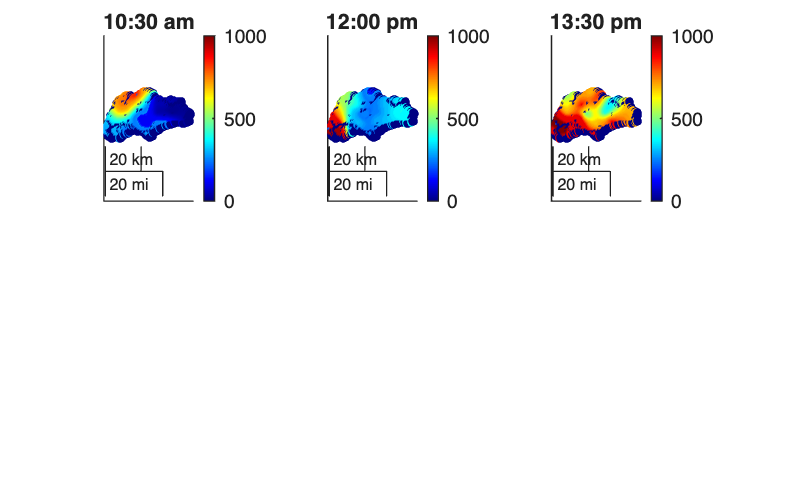

%{ %}
close all;
clear all;

SolarIrradianceData_time = ["1030", "1200", "1330"];
image_lat_lon_data = {};
for i = 1:3
    filteredDataTable_each =  readtable("../data/SolarIrradianceData/"+ SolarIrradianceData_time(i)+ ".csv");

    image_lat_lon_data{i} =  filteredDataTable_each;
end

figure (10)
textString = ["10:30 am", "12:00 pm", "13:30 pm"];  % Text to display

for plot_count = 1:length(image_lat_lon_data)

    subplot(2, length(image_lat_lon_data), plot_count);

    data = image_lat_lon_data{plot_count};  
    data = data(~isnan(data.Value), :);


    lon = data.Longitude;
    lat = data.Latitude;
    val = data.Value;
        

    geoscatter(lat, lon, 10, val, 'filled');  % 50 is the size of the marker

    geolimits([1.1667, 1.5000], [103.6, 104.05]);  % Latitude: 1°10'N to 1°30'N, Longitude: Example range
        

    geobasemap('none');

        
    % Label the plot
    title(textString(plot_count), "FontSize", 8);


    gx = gca;
        
    % Hide latitude and longitude tick labels
    gx.LatitudeAxis.TickLabels = {};
    gx.LongitudeAxis.TickLabels = {};

    % Hide latitude and longitude labels
    gx.LongitudeLabel.String  ={};
    gx.LatitudeLabel.String  ={};
        
    % Hide latitude and longitude tick marks
    gx.TickDir = 'none';

    % Hide tick marks
    gx.LatitudeAxis.TickValues = [];
    gx.LongitudeAxis.TickValues = [];

    gx.Grid = 'off';
    gx.Box = 'off';
    gx.Scalebar.Visible = 'on';
    gx.Scalebar.FontSize = 6;
    hold on;
    colormap("jet");
    colorbar;
    
    caxis([0, 1000]);

end
    


outPath = "../results/Fig1_SolarIrradiance_" +...
    string(datetime("now", "Format", "yyyy-MM-dd")) + ".pdf";

exportgraphics(gcf, outPath, ...
    'ContentType','vector', 'BackgroundColor','none');

## **Power flow on transmission network**

**10:30, 12:00, and 13:30**

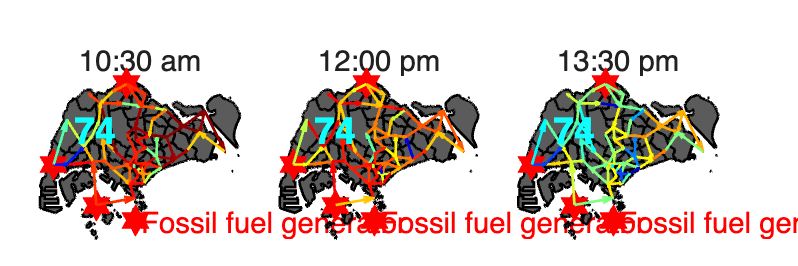

clear all;
close all;

%%% Read Singapore planning area
%%% boundary data
shpdir = '../data/mp14-plng-area-no-sea-planning-area/MP14_PLNG_AREA_NO_SEA_PL.shp';
sing = shaperead(shpdir);
info = shapeinfo(shpdir);
p1 = info.CoordinateReferenceSystem;

%%% Read power grid data: topology and
%%% centroid locations
A = readmatrix("../data/PowerGrid/A_Topology_Singapore.csv");
centroids = readmatrix("../data/PowerGrid/centroids_locations.csv");


%%%%%%%%%%%%% select mode here
mode = 1;

mode_list = ["NetLoad", "UncontrolledCharging", "V1G",...
    "V2G", "SystemLoad", "NetLoad_idealPV"];




PV_Capcacity_folder = "8_6GW/";
Optimization_method = "min_eachPLNLoadVariance";
day_simulating = 31;


PowerFlowFilePath = "../data/PowerFlow/8_6GW_Sample/" +...
            "NetLoad"+"_MAX_2050_100_LocalOpt_"+string(day_simulating)+...
            "_PowerFlow.mat";
PowerFlow_data = load(PowerFlowFilePath, 'PowerFlowMatrix');

PowerFlowFilePath_base = "../data/PowerFlow/8_6GW_Sample/" +...
            "SystemLoad"+"_MAX_2050_100_LocalOpt_"+string(day_simulating)+...
            "_PowerFlow.mat";
PowerFlow_data_base = load(PowerFlowFilePath_base, 'PowerFlowMatrix');            


for days = [1]  
    frame_all = [10.5*4, 12*4, 13*4]; 
    textString = ["10:30 am", "12:00 pm", "13:30 pm"];  % Text to display
end



fig_w_cm = 18.3;   % Nature 2-column width
fig_h_cm = 6.0;    % Height for 1×3 layout
figure('Units','centimeters','Position',[2 2 fig_w_cm fig_h_cm]);

set(groot,'defaultAxesFontName','Helvetica');
set(groot,'defaultTextFontName','Helvetica');

base_pt  = 7.0;   % tick/legend
label_pt = 8.5;   % axis labels
title_pt = 9.0;   % panel titles
line_w   = 1;




close all;
frameCount = 1;
ax_list = [];
for frame = frame_all 
    firstframe = true;

    ax = subplot(2, length(frame_all), frameCount);
    ax_list(frameCount) = ax;
    hold on;

    frame;
    dataValues = zeros(55, 1);
    index_GasGenerator = zeros(1, 3);



    P_flow = squeeze(PowerFlow_data.PowerFlowMatrix(:,:, frame));


    P_flow_netload = squeeze(PowerFlow_data.PowerFlowMatrix(:,:, :));
    Max_flow = max(abs(P_flow_netload), [], 3);
    P_flow_load_factor = P_flow./Max_flow;
    P_flow = P_flow_load_factor;



    for i = 1:length(sing)
        % Extract current planning area's geometry
        x1 = [sing(i).X];
        y1 = [sing(i).Y];
        [lat,lon] = projinv(p1,x1,y1);
        

        nanIndices = find(isnan(lon) | isnan(lat));
        startIndex = 1;
        for partIndex = 1:length(nanIndices)

            endIndex = nanIndices(partIndex) - 1;
            color_map = [50, 50, 50]./255; 
            patch(lon(startIndex:endIndex), lat(startIndex:endIndex), color_map, ...
                'EdgeColor', 'black', ... 
              'LineWidth', 1, ... 
              'FaceAlpha', 0.8); 

            startIndex = nanIndices(partIndex) + 1;
        end
    
        if startIndex <= length(lon)
            patch(lon(startIndex:end), lat(startIndex:end), color_map,...
                'EdgeColor', 'black', ... % Make edges black (or any distinct color)
              'LineWidth', 1, ...
              'FaceAlpha', 0.8); 
        end
    end

    hold on;
    
    
    scatter(centroids(25,1), centroids(25,2), 150, "filled", "hexagram","MarkerEdgeColor","none", "MarkerFaceColor","red");
    scatter(centroids(48,1), centroids(48,2), 150, "filled", "hexagram","MarkerEdgeColor","none", "MarkerFaceColor","red");
    scatter(centroids(49,1), centroids(49,2), 150, "filled", "hexagram","MarkerEdgeColor","none", "MarkerFaceColor","red");


    [n, ~] = size(centroids); % Number of nodes

    cmap = colormap("jet");

    MIN_netFlowChange_to_capac_max = 0; 
    MAX_netFlowChange_to_capac_max = 1.01;
    caxisLimits = [MIN_netFlowChange_to_capac_max, MAX_netFlowChange_to_capac_max];
    caxis(caxisLimits); 

    line_count = 1;
    for i = 1:n
        for j = i+1:n
            if A(i,j) == 1

                if P_flow(i,j) > 0
                    colorIndex = floor((P_flow(i, j) - MIN_netFlowChange_to_capac_max) / ...
                               (MAX_netFlowChange_to_capac_max - MIN_netFlowChange_to_capac_max) * size(colormap, 1)) + 1;
                    lineColor = cmap(colorIndex, :);

                    quiver(centroids(i,1), centroids(i,2), ...
                               centroids(j,1) - centroids(i,1), ...
                               centroids(j,2) - centroids(i,2), ...
                               0, 'MaxHeadSize', 0.8, 'Color', lineColor,...
                               'LineStyle', "-",...
                               'LineWidth', 1, 'AutoScale', 'on', 'AutoScaleFactor', 4); %netFlowChange_to_capac_max(i,j)

                    if ismember(line_count, [74]) 

                        mid_x = (centroids(i,1) + centroids(j,1)) / 2;
                        mid_y = (centroids(i,2) + centroids(j,2)) / 2;

                        text(mid_x, mid_y, string(line_count), ...
                         'HorizontalAlignment', 'center',...
                         'VerticalAlignment', 'middle', ...
                         'Color', [0.0588, 1.0000,1.0000], "FontSize", 14, ... 
                         'FontWeight', 'bold'); 
                    end

                
    
    
                else

                    colorIndex = min(floor((-P_flow(i, j) - MIN_netFlowChange_to_capac_max) / ...
                               (MAX_netFlowChange_to_capac_max - MIN_netFlowChange_to_capac_max) * size(colormap, 1)) + 1, size(colormap, 1));

                    quiver(centroids(j,1), centroids(j,2), ...
                               centroids(i,1) - centroids(j,1), ...
                               centroids(i,2) - centroids(j,2), ...
                               0, 'MaxHeadSize', 0.8, 'Color', lineColor,...
                               'LineStyle', "-",...
                               'LineWidth', 1, 'AutoScale', 'on', 'AutoScaleFactor', 4);
    
                    if ismember(line_count, [74]) 

                        mid_x = (centroids(i,1) + centroids(j,1)) / 2;
                        mid_y = (centroids(i,2) + centroids(j,2)) / 2;
                        

                        text(mid_x, mid_y, string(line_count ), ...
                         'HorizontalAlignment', 'center',...
                         'VerticalAlignment', 'middle', ...
                         'Color', [0.0588, 1.0000,1.0000], "FontSize", 14, ... 
                         'FontWeight', 'normal'); 
                    end
                   
                end
                line_count = line_count +1; 
            end

        end
        
    end
    
    scatter( 103.836464, 1.195, 150, "filled", "hexagram","MarkerEdgeColor","none", "MarkerFaceColor","red");

    text(103.85, 1.195, "Fossil fuel generator", "FontSize", 11, "Color","red");

    title(textString(frameCount), "FontSize", 11, 'FontWeight','normal');
    xlabel('Longitude');
    ylabel('Latitude');

    axis off;
    

    axis tight;

    frameCount = frameCount +1;
end





set(gcf, 'Position', [100, 100, 900, 300]); 

set(ax_list, 'PositionConstraint', 'outerposition'); 
set(ax_list(1), 'Position', [0.05, 0.1, 0.25, 0.6]); 
set(ax_list(2), 'Position', [0.35, 0.1, 0.25, 0.6]);
set(ax_list(3), 'Position', [0.65, 0.1, 0.25, 0.6]);




outPath = "../results/Fig1_LoadFactor_" +...
    string(datetime("now", "Format", "yyyy-MM-dd")) + "_wo_bar.pdf";

exportgraphics(gcf, outPath, ...
    'ContentType','vector', 'BackgroundColor','none');

## Local load - Line 74 (with/wo thunderstorms)

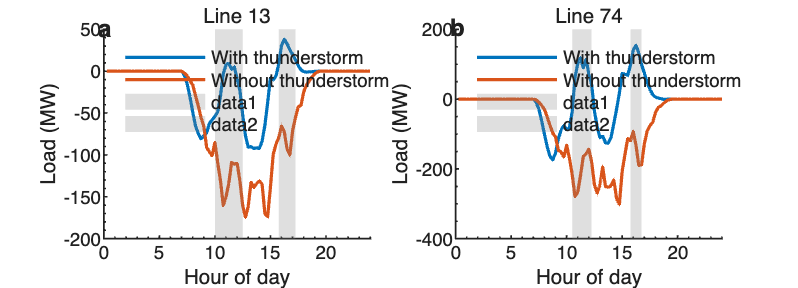


clear all; close all;


panel_w_cm = 9.0;   
panel_h_cm = 6.5;   
figure('Units','centimeters','Position',[2 2 panel_w_cm*2 panel_h_cm]);

set(groot,'defaultAxesFontName','Helvetica');
set(groot,'defaultTextFontName','Helvetica');
set(groot,'defaultAxesLineWidth',0.6);

tick_pt   = 7.0;   
label_pt  = 8.0;   
title_pt  = 9.0;   
line_w    = 1.2;   


col_thunder = [0.00 0.45 0.74];   % dark blue
col_sunny   = [0.85 0.33 0.10];   % dark red
gray_fill   = [0.5 0.5 0.5];      




hours = 0.25:0.25:24;

ax1 = subplot(1,2,1); hold on;

data_13 = readtable("../data/LineLoad/Line13Load_Net_System.csv");
data_thunder = data_13{:, 1:2};
data_sunny = data_13{:, 3:4};

plot(hours, data_thunder(:,2)-data_thunder(:,1), ...
    'LineWidth', line_w, 'Color', col_thunder, ...
    'DisplayName','With thunderstorm');
plot(hours, data_sunny(:,2)-data_thunder(:,1), ...
    'LineWidth', line_w, 'Color', col_sunny, ...
    'DisplayName','Without thunderstorm');

ylabel("Load (MW)",'FontSize',label_pt);
xlabel("Hour of day",'FontSize',label_pt);
xlim([0 24]);
title("Line 13",'FontSize',title_pt,'FontWeight','normal');
set(gca,'FontSize',tick_pt, ...
    'XMinorTick','on','YMinorTick','on', ...
    'TickDir','in','Box','off');

yLimits = ylim;
fill([10 10 12.5 12.5], [yLimits(1) yLimits(2) yLimits(2) yLimits(1)], ...
    gray_fill,'EdgeColor','none','FaceAlpha',0.25);
fill([15.75 15.75 17.25 17.25], [yLimits(1) yLimits(2) yLimits(2) yLimits(1)], ...
    gray_fill,'EdgeColor','none','FaceAlpha',0.25);

legend('Location','northwest','Box','off','FontSize',tick_pt);
text(-0.5, yLimits(2)*1.05, 'a', ...
    'FontSize',title_pt,'FontWeight','bold','FontName','Helvetica');

ax2 = subplot(1,2,2); hold on;
data_74 = readtable("../data/LineLoad/Line74Load_Net_System.csv");
data_thunder = data_74{:, 1:2};
data_sunny = data_74{:, 3:4};

plot(hours, data_thunder(:,2)-data_thunder(:,1), ...
    'LineWidth', line_w, 'Color', col_thunder, ...
    'DisplayName','With thunderstorm');
plot(hours, data_sunny(:,2)-data_thunder(:,1), ...
    'LineWidth', line_w, 'Color', col_sunny, ...
    'DisplayName','Without thunderstorm');

ylabel("Load (MW)",'FontSize',label_pt);
xlabel("Hour of day",'FontSize',label_pt);
xlim([0 24]);
title("Line 74",'FontSize',title_pt,'FontWeight','normal');
set(gca,'FontSize',tick_pt, ...
    'XMinorTick','on','YMinorTick','on', ...
    'TickDir','in','Box','off');

yLimits = ylim;
fill([10.5 10.5 12.25 12.25], [yLimits(1) yLimits(2) yLimits(2) yLimits(1)], ...
    gray_fill,'EdgeColor','none','FaceAlpha',0.25);
fill([15.75 15.75 16.75 16.75], [yLimits(1) yLimits(2) yLimits(2) yLimits(1)], ...
    gray_fill,'EdgeColor','none','FaceAlpha',0.25);

legend('Location','northwest','Box','off','FontSize',tick_pt);
text(-0.5, yLimits(2)*1.05, 'b', ...
    'FontSize',title_pt,'FontWeight','bold','FontName','Helvetica');



%{%}
% ---------- Export ----------
outPath_all = "../results/Fig1_LineLoading_13_74_Example_" + ...
              string(datetime("now","Format","yyyy-MM-dd")) + ".pdf";
exportgraphics(gcf, outPath_all, ...
    'ContentType','vector','BackgroundColor','none');

%{ %}









## **Line load with/wo thunderstorms**

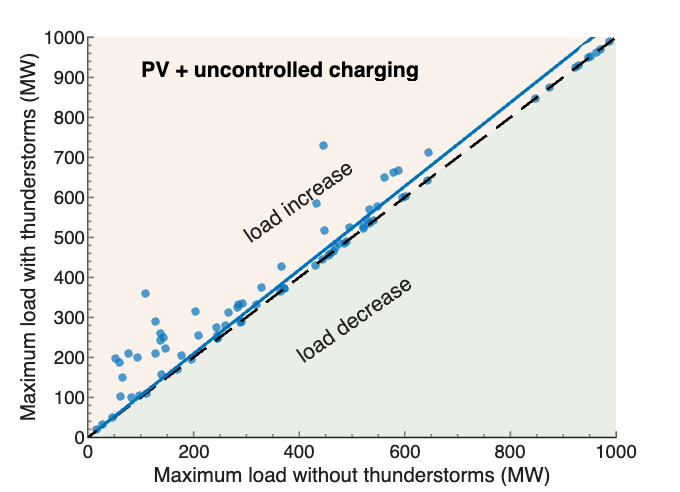

%% --- scatter + regression plot with minor ticks ---
clear all; close all; clc;


path_file_name = '../data/Data4Figure/UncontrolledCharging_with_without_thunder.csv';
UncontrolledCharging_with_without_thunder = readtable(path_file_name);
x_ori = UncontrolledCharging_with_without_thunder{:, 1};
y_ori = UncontrolledCharging_with_without_thunder{:, 2};

% Define axis limits
x_min = 0; x_max = 1000;
y_min = 0; y_max = 1000;

idx = (x_ori>=x_min) & (x_ori<=x_max);
x = x_ori(idx);
y = y_ori(idx);

% Linear regression
p = polyfit(x, y, 1); % slope & intercept
y_fit = polyval(p, x);

% Fit with intercept=0
a = (x \ y); 
y_fit0 = a * x; 

%% --- Plot ---
panel_w_cm = 9.0;   
panel_h_cm = 6.5;   
figure('Units','centimeters','Position',[2 2 panel_w_cm panel_h_cm]);

set(groot,'defaultAxesFontName','Helvetica');
set(groot,'defaultTextFontName','Helvetica');

tick_pt   = 7.0;   
label_pt  = 8.0;   
title_pt  = 9.0;   

hold on;

% --- Shaded regions ---
x_fill = [x_min, x_max, x_max, x_min];
y_fill1 = [y_min, y_max, y_max, y_max]; % above diag
y_fill2 = [y_min, y_min, y_max, y_min]; % below diag

fill(x_fill, y_fill1, [245,229,214]./255, 'EdgeColor','none','FaceAlpha',0.5); % red
fill(x_fill, y_fill2, [211,222,208]./255, 'EdgeColor','none','FaceAlpha',0.5); % green

% --- Scatter points ---
scatter(x, y, 10, [0 0.45 0.74], 'filled', 'MarkerFaceAlpha',0.7);

% --- Reference diagonal ---
plot([x_min, x_max], [y_min, y_max], 'k--', 'LineWidth', 1.0);

% --- Regression line ---
plot(x, y_fit0, '-', 'Color',[0 0.45 0.74], 'LineWidth', 1.2);

% --- Labels inside plot ---
text(300, 500, 'load increase', 'FontSize', 8, 'Rotation', 35, 'FontWeight', 'normal');
text(400, 200, 'load decrease', 'FontSize', 8, 'Rotation', 35, 'FontWeight', 'normal');


text(100, 920, 'PV + uncontrolled charging', ...
    'Color','k','FontSize',label_pt,'FontWeight','bold');



% --- Axis labels ---
xlabel("Maximum load without thunderstorms (MW)",'FontSize',label_pt);
ylabel("Maximum load with thunderstorms (MW)",'FontSize',label_pt);

xlim([x_min x_max]); ylim([y_min y_max]);

set(gca,'FontSize',tick_pt, ...
    'XMinorTick','on','YMinorTick','on', ...
    'TickDir','in','Box','off');



% --- Export ---
outPath = "../results/Fig1_MaximumLoad_with_wo_thunderstorms_" + ...
    string(datetime("now","Format","yyyy-MM-dd")) + ".pdf";
exportgraphics(gcf, outPath, ...
    'ContentType','vector','BackgroundColor','none');